# Activity 4 : Modulation Transfer Function 

### STEP 1: Averaging the images. 

EXIF data: f/1.8, 1/40s, 4.25mm

% % Load all the images
% n = 20; %number of images
% for i = 1:n
%     filename = sprintf('burst_%d.jpg', i);  % Construct the filename
%     I{i} = imread(filename);
% end
% 
% % Initialize a variable to store the sum of pixel values
% sum_of_images = zeros(size(I{1}));
% 
% % Sum up pixel values of all images
% for i = 1:n
%     sum_of_images = sum_of_images + double(I{i});
% end
% 
% % Calculate the average by dividing by the number of images
% average_image = uint8(sum_of_images / n);
% gray_ave  = rgb2gray(average_image); %converting to grayscale
% % Display the average image
% figure; imshow(gray_ave); title("average image");

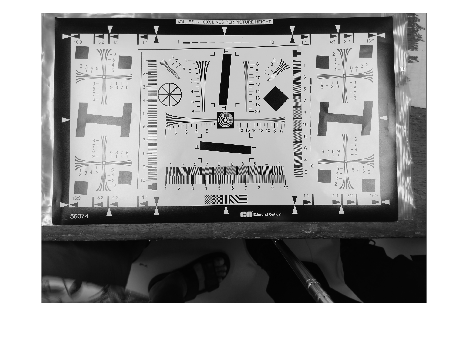

gray_ave = rgb2gray(imread('result1.jpg'));
figure;imshow(gray_ave);

### STEP 2: Choosing a Region of Interest and Extracting Intensity Profiles

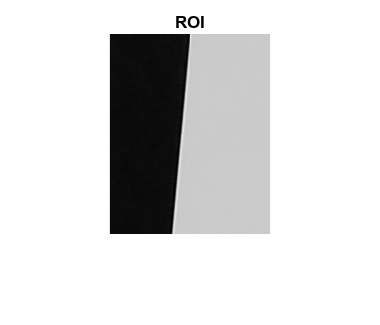

%choose a region of interest (ROI)
ROI = gray_ave(600:800, 1920:2080);
figure; imshow(ROI); title('ROI');

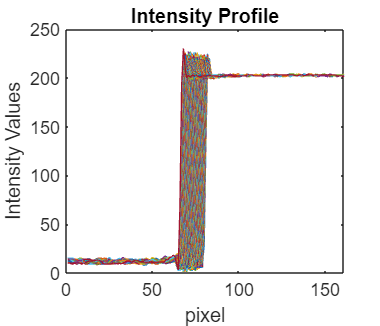


%define x-coordinates 
x_start = 1;
x_end = size(ROI, 2);

%variable to store all the profile of the line segments 
profiles = zeros(size(ROI,2), size(ROI,2));
for y = 1:1:size(ROI,2)
    xi = x_start:x_end;
    yi = y*ones(1,numel(xi));
    profiles(:, y) = improfile(ROI, xi, yi);
end

%plotting all the profiles 
plot(profiles); xlim([0 161]);
xlabel('pixel'); ylabel('Intensity Values'); title('Intensity Profile');

### STEP 3: Get the derivative and Fourier Transform

%Getting derivative of the profiles
LSF = zeros(size(ROI,2), size(ROI,2));
for y = 1:1:size(ROI, 2)
    LSF(:,y) = gradient(profiles(:,y));
end

%getting the magnitude of the FT of the LSF 
%for each line segment
FT = zeros(size(ROI,2), size(ROI,2));
for y = 1:1:size(ROI,2)
    FT(:,y) = abs(fft(LSF(:,y)));
end

%Getting the average of the FT
FT_ave = zeros(1, size(FT,2));
for y = 1:1:size(FT,2)
    FT_ave(1,y) = mean(FT(y,:));
end

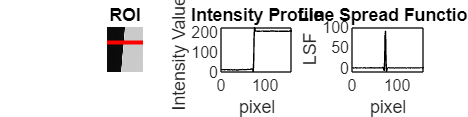

%plotting the intensity profile and LSF of a specific line segment
b = 70;   %choosing the y-coordinate

%ROI
figure('Position', [100, 100, 1200, 300]);
subplot(1,3,1); imshow(ROI); title('ROI');
hold on;
line([1 size(ROI,2)], [b b], 'Color', 'r', 'LineWidth', 2);
hold off;
%Intensity Profile
subplot(1,3,2); axis equal; plot(profiles(:,b),  'Color', 'k');
xlabel('pixel'); ylabel('Intensity Values'); xlim([0 161]);
title('Intensity Profile');
%Line Spread Function
subplot(1,3,3);axis equal; plot(LSF(:,b),  'Color', 'k');
xlabel('pixel');ylabel('LSF'); xlim([0 161]);
title('Line Spread Function');

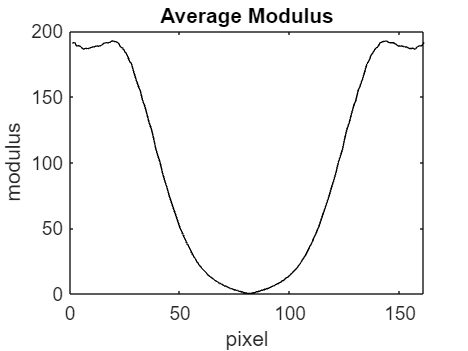



%Plotting the average modulus
figure;
plot(FT_ave, 'Color', 'k'); title('Average Modulus');
xlim([0 161])
xlabel('pixel');
ylabel('modulus');

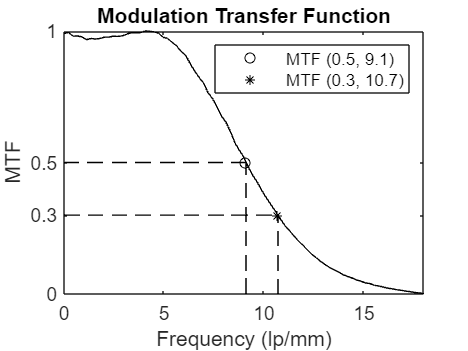

% Normalizing MTF from 0 to 1
MTF = FT_ave/max(FT_ave);

% Adjusting the frequencies 
N = length(MTF);
dx = 1/36;
Fmax = 1/(2*dx);
df = 1/((N-1)*dx);
K = round(N/2);

frequencies = [0:df:Fmax];
plot(frequencies, MTF(1:K), 'Color', 'k', 'HandleVisibility', 'off'); title(['Modulation Transfer Function']);

x_marker = 9.1; % X-coordinate of the point to be marked
y_marker = 0.5; % Y-coordinate of the point to be marked

x_marker1 = 10.7;
y_marker1 = 0.3;

yticks([0 0.3 0.5 1]);
hold on; 
plot(x_marker, y_marker, 'ko', 'MarkerSize', 5, 'DisplayName', 'MTF (0.5, 9.1)'); % 'ro' creates a red circle marker
plot(x_marker1, y_marker1, 'k*', 'MarkerSize', 5, 'DisplayName', 'MTF (0.3, 10.7)');
ylim([0 1]);
xlim([0 Fmax]);
xlabel('Frequency (lp/mm)');
ylabel('MTF');
line([0, 9.10], [0.5, 0.5], 'Color', 'k', 'LineStyle', '--', 'HandleVisibility', 'off');
line([9.10, 9.10], [0, 0.5], 'Color', 'k',  'LineStyle', '--', 'HandleVisibility', 'off');
line([0, 10.7], [0.3, 0.3], 'Color', 'k', 'LineStyle', '--', 'HandleVisibility', 'off');
line([10.7, 10.7], [0, 0.3], 'Color', 'k',  'LineStyle', '--', 'HandleVisibility', 'off');
legend('show');